# HW 16 - Ch 22 - IVPs

## Problem 1

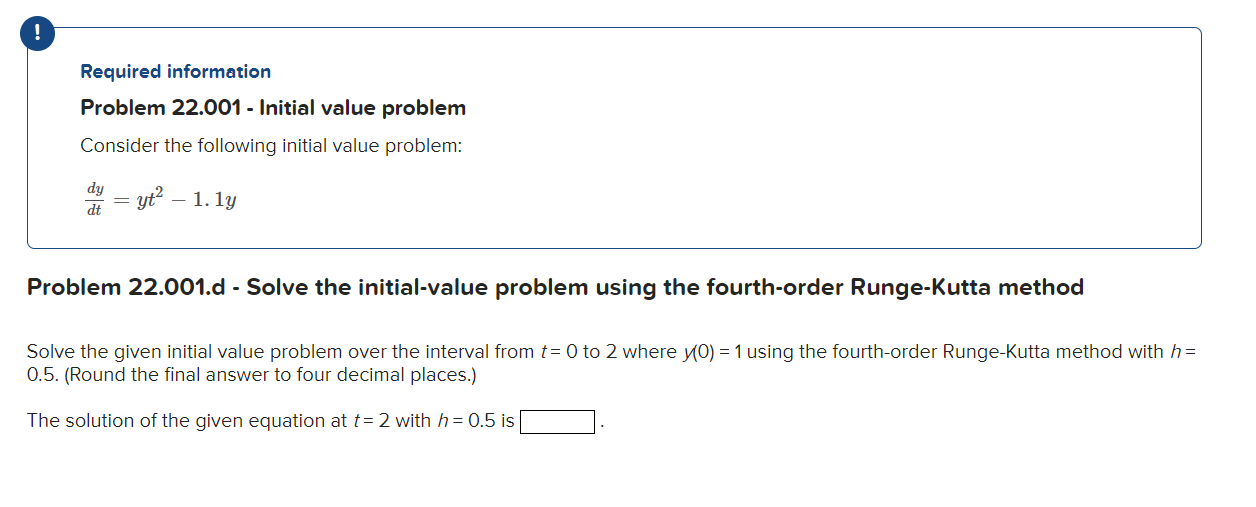

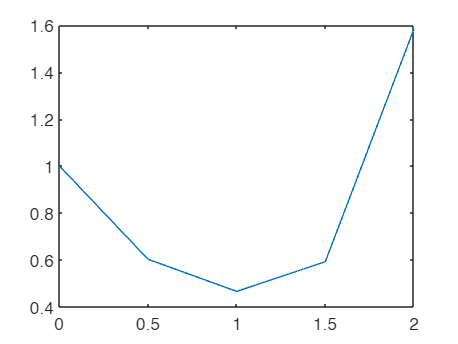

t =          0
    0.5000
    1.0000
    1.5000
    2.0000


y =     1.0000
    0.6016
    0.4645
    0.5914
    1.5845


% dydt = y*t.^2 - 1.1*y
% t = 0 -> t = 2
% y(0) = 1
% solve for t = 2 with h = 0.5 using RK4

tspan = [0 2];
y0 = 1;
h = 0.5;
[t,y] = rk4(@dydtsys, tspan, y0, h)


%The solution of the given equation at t = 2 with h = 0.5 is ... 
%   this is the value of y associated with t = 2

% RK4 advances the solution in fixed time steps h from t_i to t_f
% At each step, four slope estimates (k1–k4) are computed within the interval
% k1 uses the slope at the start, k2 and k3 at the midpoint, k4 at the end
% These slopes are combined in a weighted average to estimate the net change
% The state y is updated and stored at the next time value